# **Decompose Prices and Cluster Commodities**

Decompose each commodity price series into a long-term trend, a seasonal component, and an irregular (or business cycle) component. This operation is an additive decomposition:


$$P_t = L_t + S_t + C_t, \quad t = 1, 2, 3, \dots,$$


where:

- $P_t$ is the commodity price series.

- $L_t$ is the long-term trend.

- $S_t$ is the seasonal component (which may be the sum of multiple seasonal trends).

- $C_t$ is the irregular component.

Based on the relative similarity of the irregular components of the commodity price series, you can cluster the commodities into groups using unsupervised machine learning techniques.

### Import & Adjust Commodity Prices and Returns

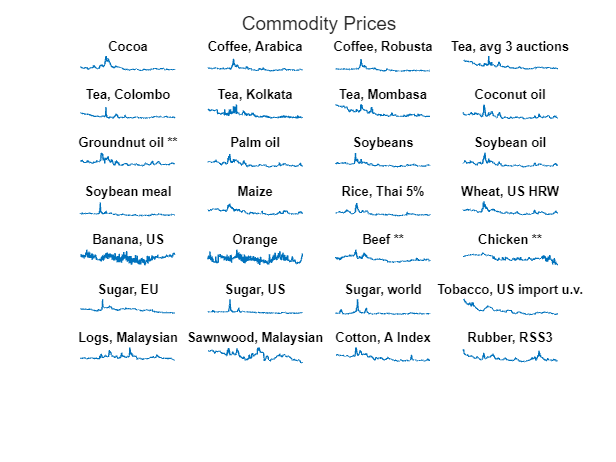

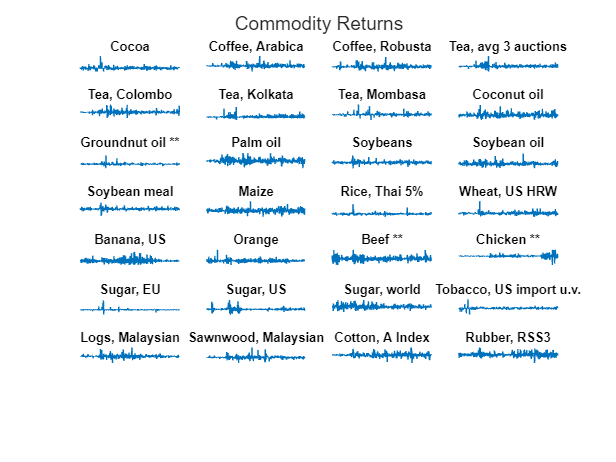

x1_ETLCommodityPricesAndReturns

### Decompose Commodity Prices

Preallocate variables for the soft commodity series components.

numObservations = height( Prices );
numCommodities = width( Prices );

longTermComponent = NaN( numObservations, numCommodities );
seasonalComponent = NaN( numObservations, numCommodities );
irregularComponent = NaN( numObservations, numCommodities );
regularComponent = NaN( numObservations, numCommodities );

Create tiled layouts for the visualization. You can visualize the trend components (for example, the sum of $L_t$ and $S_t$) separately from the irregular components ($C_t$).

figure
tlTrend = tiledlayout(8,4, "TileSpacing", "tight");
title( tlTrend, "Trend Components" )

figure
tlIrregular = tiledlayout(8,4, "TileSpacing", "tight");
title( tlIrregular, "Irregular Components")

For each soft commodity price series, perform the trend decomposition by using [trenddecomp](docid:matlab_ref.mw_a3494fa6-7826-4590-ac4d-5335c011c443).

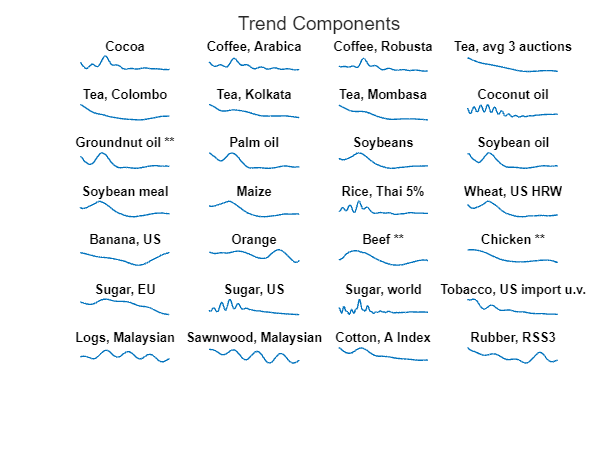

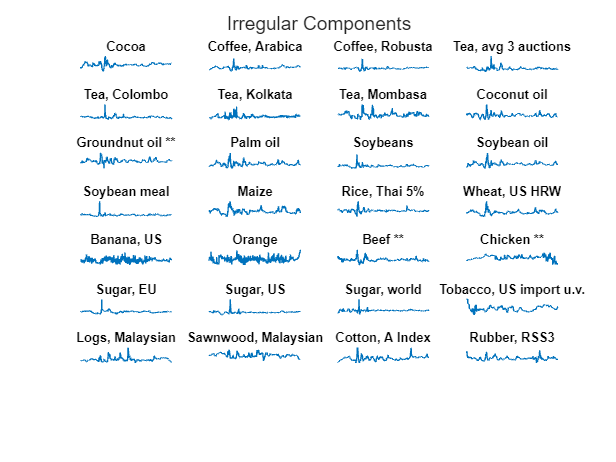

for k = 1:numCommodities

    % Decompose the price series and store the results. This process might identify 
    % more than one seasonal component, so sum the resulting matrix of seasonal 
    % components to obtain the overall seasonal trend.
    [L, S, C] = trenddecomp( Prices{:, k} );
    longTermComponent(:, k) = L;
    seasonalComponent(:, k) = sum( S, 2 );
    irregularComponent(:, k) = C;
    regularComponent(:, k) = longTermComponent(:, k) + seasonalComponent(:, k);

    % Add the components to the visualization.
    nexttile(tlTrend)
    plot(Prices.Date, regularComponent(:, k) )
    title(commodityNames(k))
    axis off

    nexttile(tlIrregular)
    plot(Prices.Date, irregularComponent(:, k))
    title(commodityNames(k))
    axis off

end

From the trend decomposition and by inspecting the series $L_t+S_t$ for each commodity, you can see that most commodities show a long-term decrease in price over recent decades, followed by a more recent upturn in the price. 

Some exceptions, such as the series *Sugar, EU*, show a long-term downward trend. 

Some commodities also appear to have gone through periods of high seasonal volatility, such as the two coffee price series. Banana and orange prices appear to be more susceptible to seasonal volatility. Chicken prices exhibit seasonal volatility that has increased in the last few years.

### Cluster Commodities Based on Similarity in Irregular Component

After removing the long-term and seasonal components from the price series, you are left with the irregular component $C_t$, given by

$C_t = P_t - L_t - S_t$.

The $C_t$ component represents the business cycle component in the soft commodity time series and this series is affected by short-term market conditions. This component provides a fairer basis for comparing the soft commodity prices because both the long-term price trends and the seasonal trends are removed.

Compute the pairwise distances between the irregular components using the correlation distance metric $d$. This metric is defined by

$d(s_1, s_2) = 1-\rho(s_1, s_2)$, where $\rho(s_1, s_2)$ is the linear correlation coefficient between the two time series $s_1$ and $s_2$.

irregularCorrDistances = pdist( irregularComponent.', "correlation" );

Use [linkage](docid:stats_ug.bssoowt-1) to perform hierarchical clustering using the correlation distances. The `complete` method uses the largest distance between commodities in the two clusters.

irregularComponentLinkage = linkage( irregularCorrDistances, "complete" );

Create a [dendrogram](docid:stats_ug.btk0xou) to visualize the linkage.

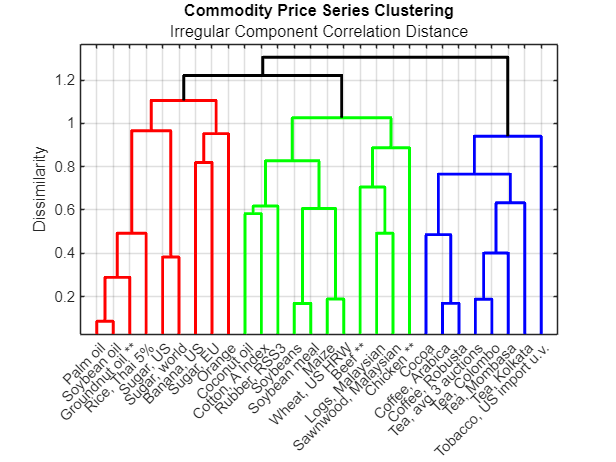

figure
h = dendrogram( irregularComponentLinkage, numCommodities, ...
    "Labels", commodityNames, ...
    "ColorThreshold", 1.2 );
ylabel( "Dissimilarity" )
title( "Commodity Price Series Clustering" )
subtitle( "Irregular Component Correlation Distance" )
set( h, "LineWidth", 2 )
xtickangle( 45 )
grid( "on" )
box( "on" )

Cluster the commodities into five groups based on their similarity obtained from this dendrogram.

numClusters = 3;
Group = cluster( irregularComponentLinkage, "maxclust", numClusters );
Commodity = string( commodityNames.' );
clusteredCommodities = table( Commodity, Group );
commoditiesByCluster = sortrows( clusteredCommodities, "Group" );
disp( commoditiesByCluster )

            Commodity            Group
    _________________________    _____

    "Coconut oil"                  1  
    "Soybeans"                     1  
    "Soybean meal"                 1  
    "Maize"                        1  
    "Wheat, US HRW"                1  
    "Beef **"                      1  
    "Chicken **"                   1  
    "Logs, Malaysian"              1  
    "Sawnwood, Malaysian"          1  
    "Cotton, A Index"              1  
    "Rubber, RSS3"                 1  
    "Groundnut oil **"             2  
    "Palm oil"                     2  
    "Soybean oil"                  2  
    "Rice, Thai 5%"                2  
    "Banana, US"                   2  
    "Orange"                       2  
    "Sugar, EU"                    2  
    "Sugar, US"                    2  
    "Sugar, world"                 2  
    "Cocoa"                        3  
    "Coffee, Arabica"             

### Cluster Commodities Based on Similarity in Regular Component

The regular component is the sum of the long-term and seasonal trends $L_t+S_t$, and is equal to $P_t-C_t$, the commodity price series without its irregular (business cycle) component.

Evaluate the pairwise distances and the corresponding linkage.

regularCorrDistances = pdist( regularComponent.', "correlation" );
regularComponentLinkage = linkage( regularCorrDistances, "complete" );

Create a [dendrogram](docid:stats_ug.btk0xou) to visualize the linkage, and then select a threshold to achieve three clusters.

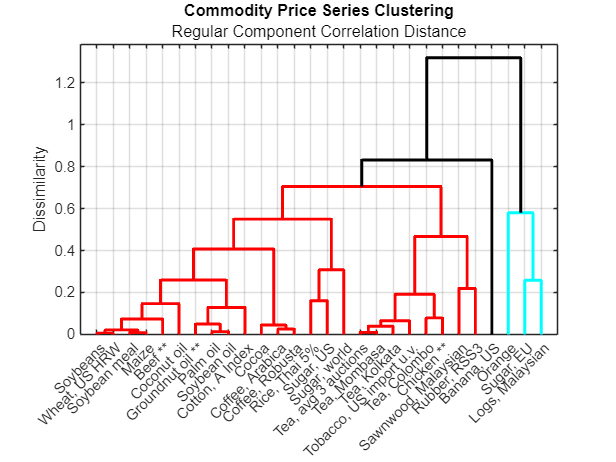

figure
h = dendrogram( regularComponentLinkage, numCommodities, ...
    "Labels", commodityNames, ...
    "ColorThreshold", 0.8 );
ylabel( "Dissimilarity" )
title( "Commodity Price Series Clustering" )
subtitle( "Regular Component Correlation Distance" )
set( h, "LineWidth", 2 )
xtickangle( 45 )
grid( "on" )
box( "on" )

You might expect the volatility in the commodities to manifest itself in the irregular component, rather than the regular component. For this reason, continue with the clusters identified by performing hierarchical clustering on the irregular components of the commodity price series. However, clustering on the regular components provides a useful grouping of the commodities based on their combined long-term and seasonal trends. From the dendrogram, you can see that both oranges and bananas have a dissimilar regular profile to the other commodities.

### Visualize Clusters in 3D

Embed the commodities in a lower-dimensional space by using classical multi-dimensional scaling using [cmdscale](docid:stats_ug.brx09qj-395).

lowerDim = 3;
Y = cmdscale( irregularCorrDistances, lowerDim );

Visualize the embedding. Add the convex hull of each group using [convhull](docid:matlab_ref.f80-999588) to illustrate the different groupings in 3-dimensional space.

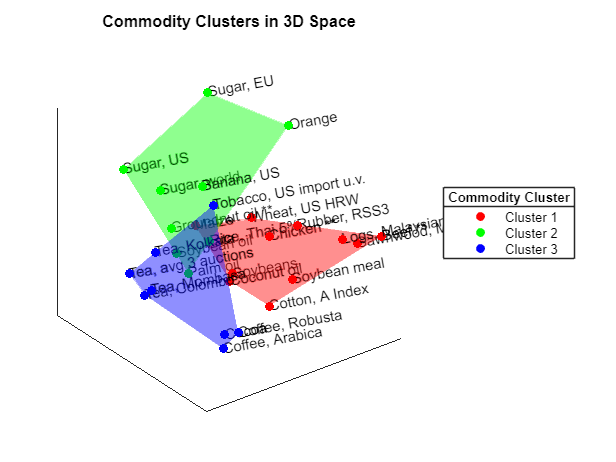

figure
view( 3 )
clusterColors = hsv( numClusters );
colormap( clusterColors )
hold( "on" )

for k = 1:numClusters
    % Extract coordinate data for the current group.
    idx = clusteredCommodities.Group == k;
    clusterx = Y(idx, 1);
    clustery = Y(idx, 2);
    clusterz = Y(idx, 3);
    color = clusterColors(k, :);
    % Evaluate the convex hull.
    ch = convhull( clusterx, clustery, clusterz );
    % Visualize the convex hull, its vertices (the commodities), and create
    % text labels.
    trisurf( ch, clusterx, clustery, clusterz, ...
        "FaceColor", clusterColors(k, :), ...
        "FaceAlpha", 0.25, ...
        "EdgeColor", "none", ...
        "HandleVisibility", "off" )
    scatter3( clusterx, clustery, clusterz, ...
        [], clusterColors(k, :), "filled", "DisplayName", "Cluster " + k )
    text( clusterx, clustery, clusterz, ...
        clusteredCommodities.Commodity(idx), "Rotation", 10 )
end

xticks( [] )
yticks( [] )
zticks( [] )
title( "Commodity Clusters in 3D Space" )
lg = legend( "Location", "eastoutside" );
title( lg, "Commodity Cluster" )